addpath('Clay Testing Format')

## Part Two - Performance Criteria, Improved Lyapunov Stability Arguments, and Nonlinear Variable Structure Controller 

### Performance Criteria

A nonlinear control scheme is desired that can take the state from $\overset{\rightharpoonup}{x_0} ~=~(110^^\circ,0)$ to the upward operating point within five seconds. It is desired to have a final velocity of zero and a steady state angular error of less than half a degree. It is also desired to eliminate chatter in the actuator at steady state - only controllers with zero steady state chatter can be considered successful. Finally, the controller must be robust to model and parameter inaccuracies.

### Expanded Lyapunov Stability 

The stability analysis in part one utilized Lyapunov's indirect method which had severe limitations. It is desired to utilize a Lyapunov-stability-based control technique that holds for a much larger region of the state space. A control law that is guaranteed to make the desired equilibrium point attractive globally is the ideal scenario. It is shown that this ideal scenario is not achievable with the proposed control law given that the system is effort limited (15 V rails). Additionally, the 100Hz measurement sample rate for the system is not considered in the stability analysis. Rather, it will be compensated for with an additional control structure; a boundary layer that takes over near the switching surface. 

#### Defining Lyapunov Function $V(s)$ and Switching Surface $s(\overset{\rightharpoonup}{x}) ~=~0$ 

A Lyapunov function $V(s)$ is defined in terms of scalar $s(\overset{\rightharpoonup}{x})$ such that it is positive definite. The scalar is defined:


$$s(\overset{\rightharpoonup}{x}) ~=~ \dot{\theta} + \lambda\theta$$


syms lambda v_hat v_o v_s s s_dot eta K


s_eqn = s == theta_dot + lambda*theta; 

The equation $s(\overset{\rightharpoonup}{x}) ~=~0$ describes a surface in the state space. On this surface, a decaying linear polynomial in phase variables is realized. If scalar $V(s)$ is defined as:


$$V(s) ~=~ \frac{s^2}{2}$$


then $V(s)$ is positive definite. When $V(s)$ is minimized, the system is on the switching surface and the states will decay to zero asymptotically. On the switching surface


$$ \dot{\theta} + \lambda\theta ~=~ 0$$


and


$$\theta(t + t_{tp}) ~=~ e^{-{\lambda}(t-t_{tp})}\theta(t_{tp})$$


where $t_{tp}$ is the transport time; the time when the system reached the switching surface, and $t$ is the current time. 

#### Negative Definiteness of $\dot{V}(s)$

To prove asymptotic stability, $\dot{V}(s)$ must be negative definite. This is where the control law enters consideration. A control actuation will be selected such that, through state feedback, $\dot{V}(s)$ can be made negative definite. It is shown here that there are practical limitations to this; but an effective control law can still be designed for the real input limited system. 


$$\dot{V}(s)  ~=~ s\dot{s}(s)$$


where $\dot{s}(s)$ denotes the derivative of $s(\overset{\rightharpoonup}{x}) $ formulated explicitly in terms of $s$. The derivative cannot be formulated in this manner immediately, so for now:


$$\dot{s}(\overset{\rightharpoonup}{x}, v_m) = \ddot{\theta}(\overset{\rightharpoonup}{x}, v_m)  + \lambda\dot\theta$$
 

s_dot_eqn = s_dot == theta_ddot + lambda*theta_dot;
s_dot_eqn = subs(s_dot_eqn, theta_ddot, rhs(isolate(ModPendulumEOM , theta_ddot)));

Using terms from $\ddot{\theta}$, $\dot{s}(\overset{\rightharpoonup}{x}, v_m)$ can be rewritten. 


$$\ddot{\theta}(\overset{\rightharpoonup}{x}, v_m) 

~ =~
\frac{L\,M\,g\,\sin \left(\theta \right)-T_{\textrm{ba}} \,\mathrm{sign}\left(\dot{\theta} \right)-\frac{K_c \,N\,\dot{\theta} }{K_m \,R_a }}{J_m \,N+J_p }

~+~ \frac{K_c \,v_m }{R_a(J_m \,N+J_p) }}

~=~

f(\overset{\rightharpoonup}{x})+ bv_m$$


theta_ddot_eqn = NL_PendulumSS(2);

where 


$$f(\overset{\rightharpoonup}{x}) = \frac{L\,M\,g\,\sin \left(\theta \right)-T_{\textrm{ba}} \,\mathrm{sign}\left(\dot{\theta} \right)-\frac{K_c \,N\,\dot{\theta} }{K_m \,R_a }}{J_m \,N+J_p }$$


f = rhs(theta_ddot_eqn - b*v_m);

and 


$$b ~=~ \frac{K_c  }{R_a(J_m \,N+J_p) }}$$


b = B(2);
b_n = double(subs(subs(b, [L, M, g, J_m, J_p, N, K_m, T_ba]...
    ,[L_n, M_n, g_n, Jm, Jp, N_n, Km, T_ba_n]), K_c/R_a, KcRa));

hence


$$\dot{s}(\overset{\rightharpoonup}{x}, v_m)  ~=~ f(\overset{\rightharpoonup}{x})+ bv_m + \lambda\dot{\theta}$$


It is desired to eliminate explicit dependance on the state of the nonlinear system from the Lyapunov function's derivative. If $\dot{V}(s)$, which is more generally a function of the state (i.e. $\dot{V}(\overset{\rightharpoonup}{x})$), can be kept in terms of $s$ alone, then the negative definiteness can be a reasoned in a straightforward manner. To achieve this, the nonlinearities of the plant are cancelled out, and $\dot{s}$ is driven to zero, via a nullifying actuation voltage $\hat{v}$. 


$$\hat{\dot{s}} ~=~ \hat{f}(\overset{\rightharpoonup}{x})+ b\hat{v} + \lambda\dot{\theta}~=~0$$



$$

\hat{v} ~=~ -\frac{1}{b}(\hat{f}(\overset{\rightharpoonup}{x})+\lambda\dot{\theta})$$



$$\hat{v} =

-\frac{R_a{\left(J_m \,N+J_p \right)}}{K_c } 

\,{\left( \frac{L\,M\,g\,\sin \left(\theta \right)-T_{\textrm{ba}} \,\mathrm{sign}\left(\dot{\theta} \right)-\frac{K_c \,N\,\dot{\theta} }{K_m \,R_a }}{J_m \,N+J_p }

~+ ~

\lambda \,\dot{\theta}\right)}\,$$


where $\hat{f}(\overset{\rightharpoonup}{x})$ is the best estimate available of $f(\overset{\rightharpoonup}{x})$. An additional actuation $v_s(s)$, a feedback law on $s$,  is added to $\hat{v}$ to give the total control actuation $v_m$.


$$v_m ~=~ \hat{v} + v_s(s)$$


Using this input, $\dot{s}$ is 


$$\dot{s}(\overset{\rightharpoonup}{x}, \hat{v}, s)  ~=~ f(\overset{\rightharpoonup}{x})+ b(\hat{v} + v_s(s)) + \lambda\dot{\theta}$$



$$\dot{s}(\overset{\rightharpoonup}{x}, s)  ~=~ 


f(\overset{\rightharpoonup}{x})

-

\hat{f}(\overset{\rightharpoonup}{x})-\lambda\dot{\theta}

+ 


 b v_s(s)+ \lambda\dot{\theta}$$



$$\dot{s}(\overset{\rightharpoonup}{x}, s)  ~=~ 


F(\overset{\rightharpoonup}{x})

+ 

 b v_s(s)$$


**First Practical Limitation on Proof of Negative Definiteness - Model Uncertainty**

Above, $F(\overset{\rightharpoonup}{x})$ represents a mismatch between the model and the real system. This is not a completely satisfactory result because $\dot{s}$ is not a function of $s$ alone. Therefore, the model uncertainty is the first limitation on a proof of negative definiteness that encorporates a feedback law on $s$. 


$$\dot{V}(\overset{\rightharpoonup}{x}, s) 

~=~


s(F(\overset{\rightharpoonup}{x})

+ 

 b v_s) ~<~ 0  $$
 

i.e. 


$$sbv_s ~<~ -sF(\overset{\rightharpoonup}{x})$$


If $v_s$ is not made large enough in magnitude, this inequality will surely fail. 

**Second Practical Limitation on Proof of Negative Definiteness - Saturated Actuation**

The second limitation comes from the voltage rails. The bounds on the actuation are  $\pm 15V$, 


$$|v_m| ~=~ |\hat{v} + v_s| \leq 15[V]$$
 

Therefore, a trajectory requiring too much nullifying voltage at any point in time will saturate the actuator and $v_s$ will have additional requirements. When this happens, $\hat{\dot{s}}  \neq 0$ and 


$$

\hat{v} ~=~ -\frac{1}{b}(\hat{f}(\overset{\rightharpoonup}{x})+\lambda\dot{\theta} - \hat{\dot{s}})$$



$$\dot{s}(\overset{\rightharpoonup}{x}, s)  ~=~ 


F(\overset{\rightharpoonup}{x})



+ \hat{\dot{s}}

+ 


 b v_s(s)

$$



$$\dot{V}(\overset{\rightharpoonup}{x}, s) 

~=~


s(F(\overset{\rightharpoonup}{x})



+ \hat{\dot{s}}

+ 


 b v_s(s)) ~<~ 0  $$
 

Where now the condition for negative definiteness is affected by the value of $\hat{\dot{s}}$. This report will not address the possibility of reducing the model uncertainty, but the $\lambda$ and a switching gain $K$will be tuned manually to ensure that, for our scenario, $\hat{\dot{s}}$ is zero and $\hat{v}$ does not hit $\pm 15V$. 

### Nonlinear Variable Structure Controller Design

A control law with three meta-structures is proposed. The first is a switching law for $v_s$ that keeps $s ~=~0$ attractive in the presence of model uncertainty. 


$$v_s = -\frac{K}{b}sign(s)$$


The second is a smoothing proportional controller on $s$ that is implemented near a boundary layer. The discrete measurements available for feedback are shown to produce chatter in the actuator and an undesirable amount of swinging about the equilibrium point. If the system is slowed down near the switching surface, this chatter is reduced or eliminated. 


$$v_s = -\frac{K}{b}C_{BL}s$$


The combination of the first two meta-structures is implemented as a saturation control law with suitably chosen pre and post-multiplying gains. The pre-multiplying gain $C_{BL}$ will control the size of the boundary layer along with the aggressiveness of the linear control law on $s$. The post multiplying gain $\frac{K}{b}$ will control the magnitude of the switching law outside the boundary layer. 

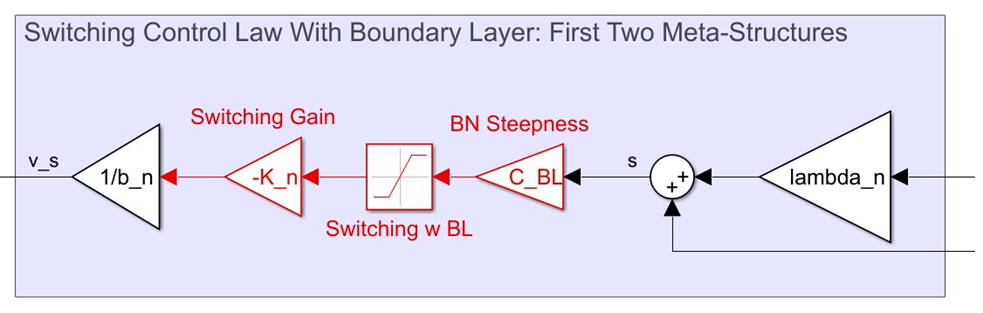

The third meta structure is a zeroing of all actuation if a condition on $\theta$ is met. The actuation will cease entirely if $|\theta|$ becomes suitably small. When this occurs, the static friction present in the system will take over, the actuation effort will cease, and an acceptable amount of steady state error will be present. Any steady state error present in the first two structures will result in actuation that simlpy burns energy. If the control law evaluates to a constant voltage output at steady state and the system has reached an equilibrium with the static friction, the control effort is being dissipated as heat by the armature resistance. Additionally, if the boundary layer fails to prevent chatter, this law has a chance of preventing that and allowing the stiction to produce steady state stability. 

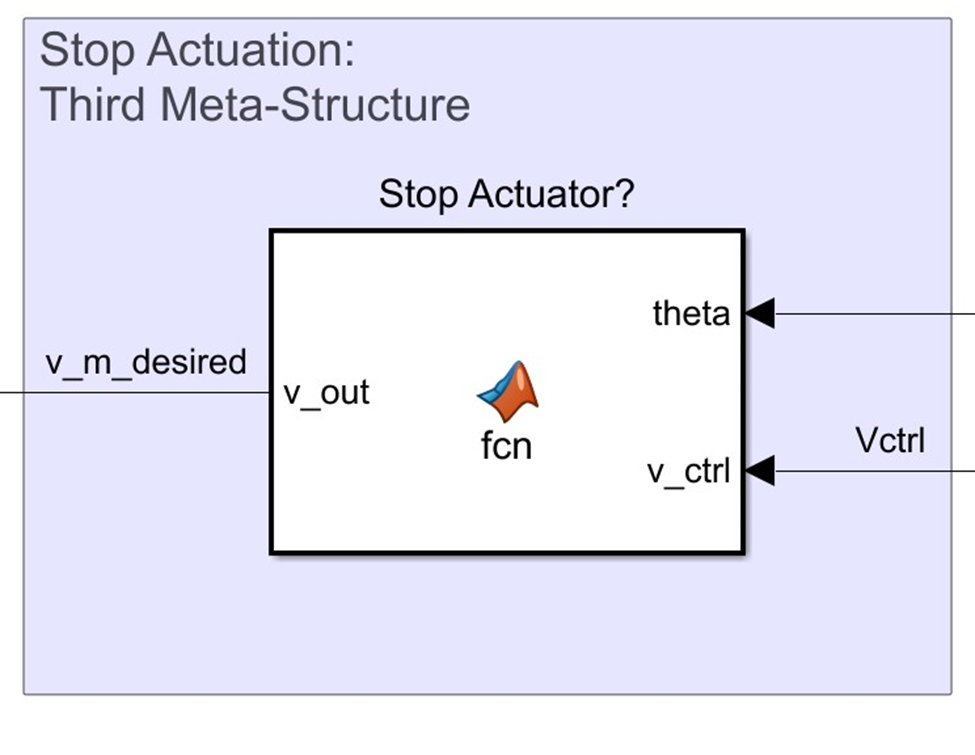

#### Switching Control Law

If the $\hat{v}$ condition is satisfied for a particular trajectory, then negative definiteness is only hindered by the model uncertainty. If this is reasonably small, then the following switching law is guaranteed negative definite to small $s$. 

- **Derivation of Law and Criteria For ND Given System Rails**

- **Show Simulink Model and dive into specifics of the implementation**

- **Continuous Sample Time SIMULATION**

- **Deterioration With Discrete Sample Time (Motivates Boundary Law) SIMULATION**

#### Smoothing Boundary Layer

Two control law structures are proposed, one for transport that makes $\dot{V}(s)$ as negative as possible given the voltage rails, and one that uses smoother actuation nearer the $s = 0$